filename = "testing1D_K6.mat"; % k=6
%filename = "testing1D_K10.mat"; % k=10
hasMatFile = isfile(filename);
if (hasMatFile)
    load(filename);
end

### Original signal

Combination of 3 frequency

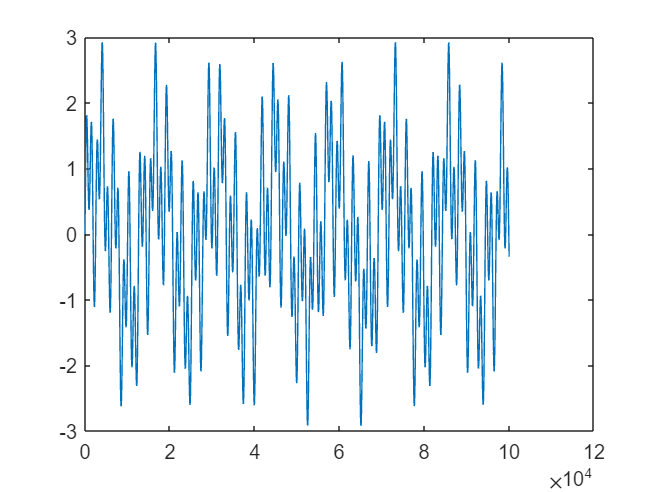

if (~hasMatFile)
    fs = 100;
    t = 0:1/fs:1000;
    f=[2,5,22];
    signal = zeros(1,length(t));
    for fi=f
        signal = signal+sin(t/fi); % coi lai
    end
end
figure('Name','Clear signal');
plot(signal)

### Raw signal

Add noise to signal

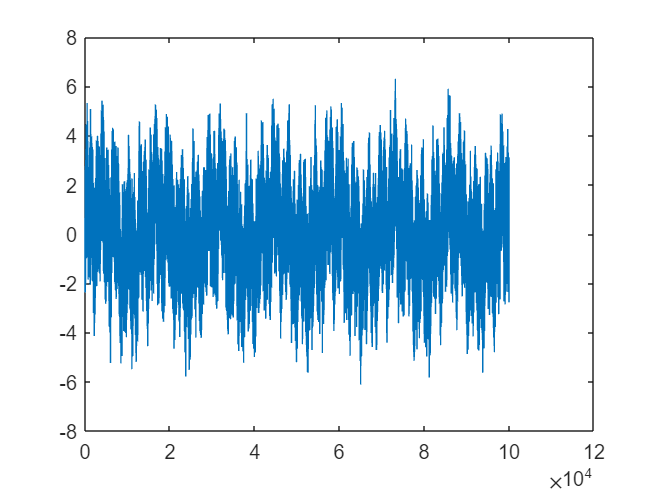

if (~hasMatFile)
    noise = wgn(1,length(t),0);
    raw = signal+noise;
end
figure('Name','Raw signal');
plot(raw);

% psnr
psnr_or = psnr(raw, signal);

### Seperate 5 IMF

if (~hasMatFile)
    % parameters:
    alpha = 5000;       % bandwidth constraint
    tau = 0.25;         % Lagrangian multipliers dual ascent time step
    K = 6;              % number of modes
    DC = 1;             % includes DC part (first mode at DC)
    
    init = 1;           % initialize omegas randomly, may need multiple runs!
    
    tol = K*10^-6;      % tolerance (for convergence)
    
    [u, u_hat, omega]=VMD(raw, alpha, tau, K, DC, init, tol);
end

### Loop for G

G_range = 1:K;
filterType_list = ["wiener","mean","median"];
psnr_v = zeros(K+1,1+length(filterType_list));
psnr_v(1,1) = psnr_or;
for G=G_range

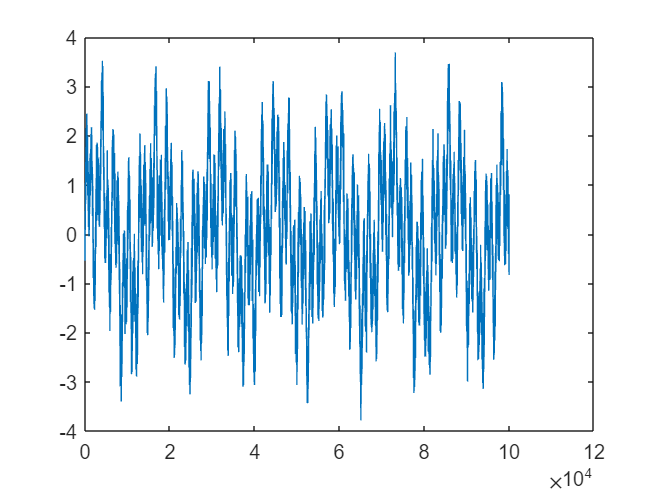

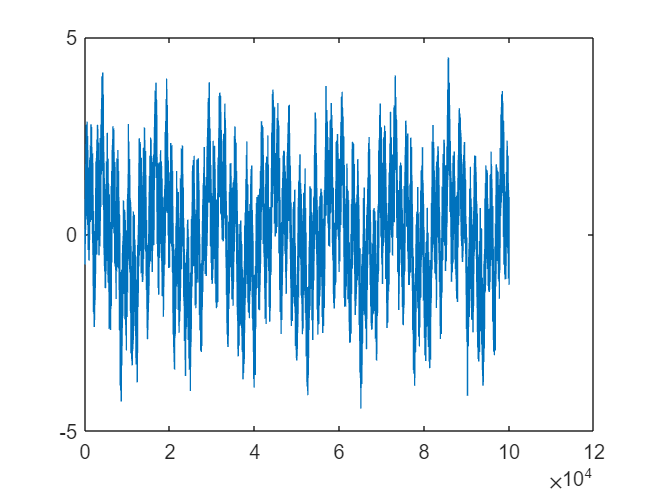

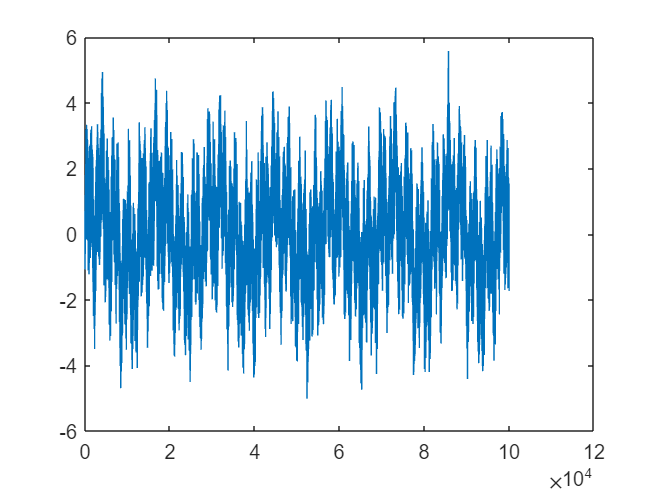

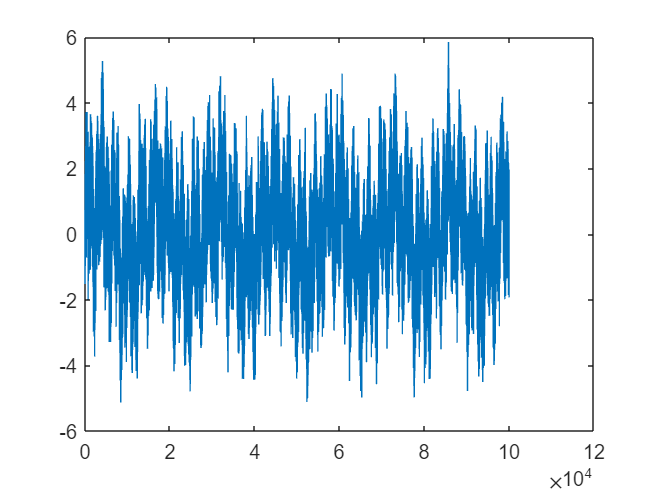

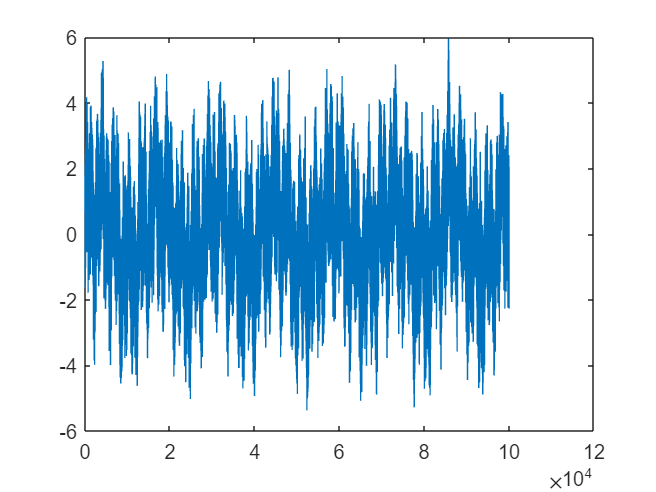

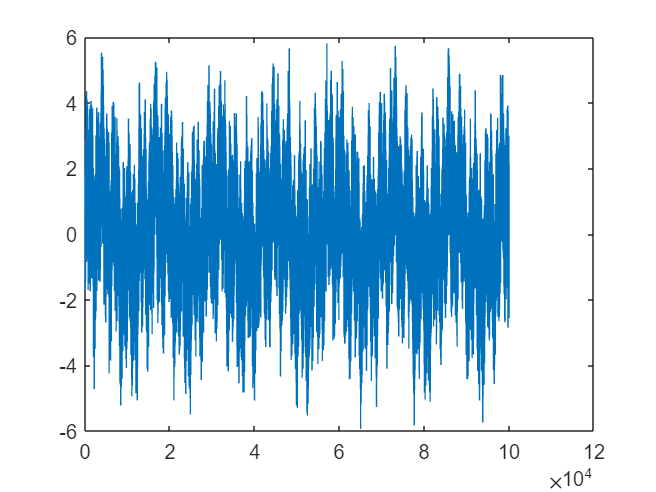

%G = 2; % get G IMR out of K
recontruct = u(1:G,:);
if G>1
    recontruct = sum(u(1:G,:));
end
figure('Name','VMD signal');
plot(recontruct);

psnr_v(G+1,1) = psnr(recontruct, signal);

### Filter noisy signal

for fi=1:length(filterType_list)

filterType = filterType_list(fi);
filtered_signal =getFiltered(raw,filterType);
% figure('Name','filtered signal');
% plot(filtered_signal);
psnr_v(1,fi+1) = psnr(filtered_signal, signal);

### Residual calculate + filter

residual = raw - recontruct;
filtered_residual = getFiltered(residual,filterType);
removednoise = filtered_residual+recontruct;
psnr_v(G+1,fi+1) = psnr(removednoise, signal);

end

end

writematrix(psnr_v,"PSNR_K"+K+".csv")

### Plot PSNR

figure('Name','Summary');
b1 = bar(psnr_v);
ylabel("PSNR");
plotNumber(b1);
legend(["Not depend on filter" filterType_list]);
xticklabel = {"Noisy signal"};
for  G=G_range
    xticklabel{G+1} = ""+G+"/"+K+ " IMF";
end
set(gca,'xticklabel',xticklabel);

function plotNumber(b)
    xtips1=[];
    ytips1=[];
    labels1=[];
    for i=1:length(b)
        xtips1 = b(i).XEndPoints;
        ytips1 = b(i).YEndPoints;
        data = b(i).YData;
        labels1 = string(round(data,2));
        xtipp = [];
        ytipp = [];
        labelsp =[];
        xtipn = [];
        ytipn = [];
        labelsn =[];
        countp=1;
        countn=1;
        for l=1:length(data)
            if data(l)<0
                labelsn(countn)=labels1(l);
                xtipn(countn)=xtips1(l);
                ytipn(countn)=ytips1(l);
                countn = countn+1;
            else
                labelsp(countp)=labels1(l);
                xtipp(countp)=xtips1(l);
                ytipp(countp)=ytips1(l);
                countp = countp+1;
            end
        end
        text(xtipp,ytipp,string(labelsp),'HorizontalAlignment','center','VerticalAlignment','bottom');
        % negative value
        text(xtipn,ytipn,string(labelsn),'HorizontalAlignment','center',...
        'VerticalAlignment','top')

    end
end
function filtered_signal=getFiltered(raw,filterType)
    filtered_signal =[];
    switch filterType
        case "wiener"
            filtered_signal = wiener2(raw);
        case "median"
            filtered_signal = medfilt1(raw);
        case "mean"
            windowSize = 5; 
            b = (1/windowSize)*ones(1,windowSize);
            a = 1;
            filtered_signal = filter(b,a,raw);
    end
end

